clear fig
%getting data
table = readtable("StarTypeDataset.csv");

data = table{:, :}

data =     0.7772   -0.1422
    0.8037   -0.1445
    0.9215   -0.1639
    0.8079   -0.1514
    1.0000   -0.1869
    0.8258   -0.1514
    0.8401   -0.1579
    0.8502   -0.1595
    0.8527   -0.1583
    0.7756   -0.1522


temp = data(:, 1);
magn = data(:, 2); 

%plotting data 
plot(temp, magn, 'x')
hold on 

%getting cluster centers from my function
[centers, IDX, variance] = MyKmeans(data,10)

centers =    -0.2063    0.1613
    0.1162   -0.0253
    0.8569   -0.1490
    0.5940   -0.0963
    0.4716    0.2369
   -0.6013    0.4595
   -1.2426    0.0606
   -0.6730    0.8131
   -0.6343    0.0382
   -1.0382   -0.6454


IDX =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


variance = 0.2148

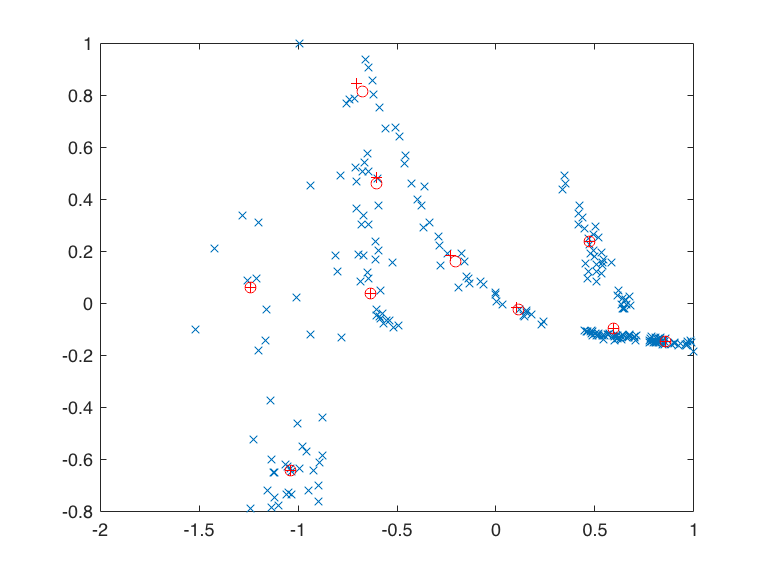

plot(centers(:, 1), centers(:, 2), 'or')

%getting cluster centers from matlab function
[idx, centersTest] = kmeans(data, 10);
plot(centersTest(:, 1), centersTest(:, 2), '+', 'Color', 'red')

hold off

figure

